%----straight line initial condition

%number of points in the trajectory
traj_pt = 200;

%List of roots
pos_root_arr = double(pos_root_arr)

pos_root_arr =     0.7999    0.3106    0.1206
    0.2001    0.0194    0.0019
    1.9000    1.7525    1.6164


hc_net

hc_net =      1     3     2


%start & end point
start_idx = 3; end_idx = 1;

%get straight line initial condition joining the end points
q_IC = straight_line_IC(traj_pt,pos_root_arr,start_idx,end_idx);


%For descent 
traj = q_IC;

%lift trajectory
[mom_traj, dt_traj] = lift_traj(traj, eqns_fsolve_fun,Jac_eqns_fsolve_fun,Ham_fun_qp);

%get phase space trajectory and functional gradient 
num_smooth = 10

num_smooth = 10

[PS_traj, delta_x, t_traj] = PS_traj_and_func_grad(traj, mom_traj, ...
    dt_traj, dHamdq_fun,num_smooth);
  

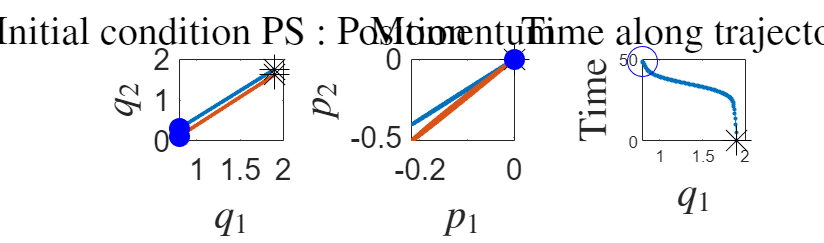

plotnam = "Initial condition PS";
save_plot_name = 'Examples\Plots\'+model_nam+'_IC_PS_traj.png';
save_plot_flag = 0; %change to 1 to save
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,save_plot_flag)